%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% QUAD-ROTOR ATTITUDE CONTROL                                             %
% Author:  Soufiane El Omari (soufiane.elomari@polimi.it)                 %
% Date: 13/12/2021                                                        %
% This script contains a MATLAB implementation of a system                %
% identification and estimation project. The goal of this project is to   %
% estimate the parameters of a dynamic system using grey-box modeling and %
% optimize the excitation signal to reduce parametric uncertainty.        %
% The model used is a linearized and decoupled at low speed, the          %
% derivation of which is not covered in this work. Feel free to use any   %
% model and adjusting the requirements/inputs.                            %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Close all figures, clear workspace, and command window
close all
clear
clc

## **System identification from simulated data for a given input**

Grey-box estimation methods use a set of measured data and a model class to find a fit for the model parameters, both in time and frequency domains. This model is linearized using Poisson's formula and works only under the assumption of low speed to neglect couplings of dynamic modes. 

### Model Class

The model class is obtained from the decoupled equations of motion in the longitudinal direction.

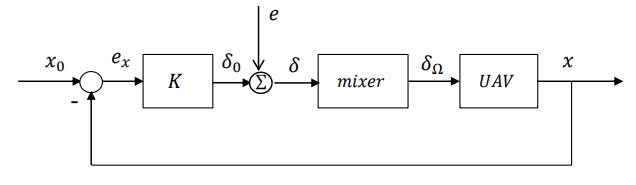

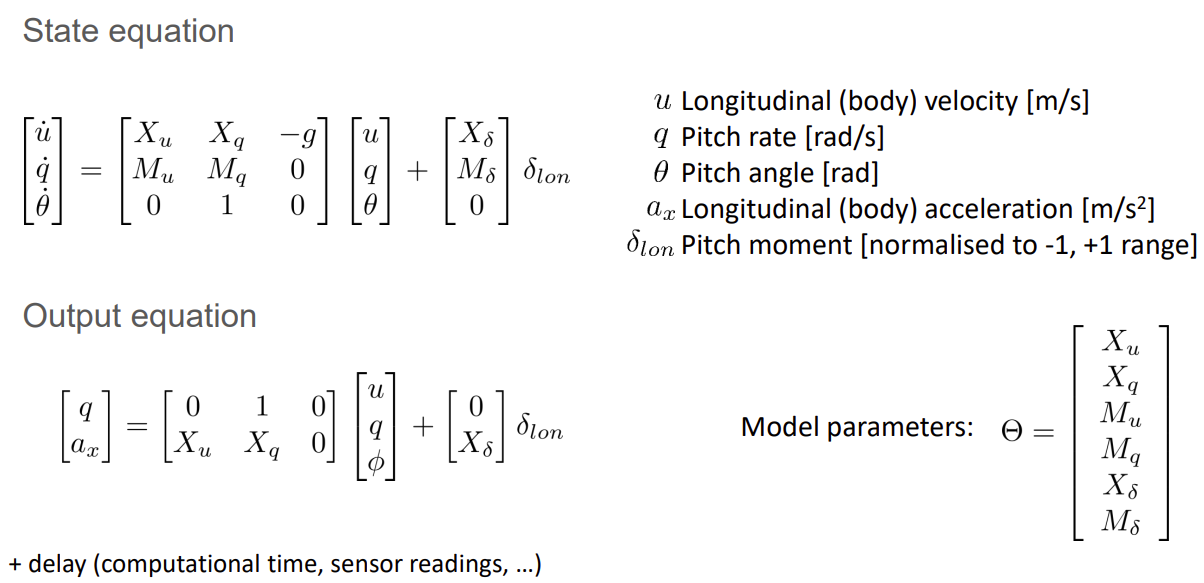

### Data

The simulated output of the longitudinal dynamics is used as the initial model data. The data set will be expressed in frequency domain, since the system is only stable under attitude and position feedback. The data in frequency domain is obtained using a fast Fourier transform fft().

%% Problem statement
load('mydata.mat')  % Set of response data from the lab flight testing of the drone
load('ExcitationM.mat') % Excitation sequence used for generating the data set (Linear sweep)
RealValues = [-0.1068 0.1192 -10.1647 -5.9755 -2.6478 450.71]'; % Nominal model values, used for comparison
[Ar,Br,Cr,Dr] = model2(RealValues(1),RealValues(2),RealValues(3),RealValues(4),RealValues(5),RealValues(6),250);
realmodel=ss(Ar,Br,Cr,Dr);
% Problem data
Mtot=MYDATA.Mtot; ax=MYDATA.ax;
q=MYDATA.q; tout=MYDATA.tout;
theta=MYDATA.theta; x0=MYDATA.x0;
N=26646; t = linspace(1,104,N);

% Computing the sampling frequency
time_diff = diff(ExcitationM(:,1));
instantaneous_freq = 1 ./ time_diff;
mean_sampling_freq = mean(instantaneous_freq);
disp(['Mean Sampling Frequency: ' num2str(mean_sampling_freq) ' Hz']);

Mean Sampling Frequency: 249.2006 Hz


Fs=mean_sampling_freq; Ts=1/Fs; N=26531;
data = iddata([q,ax],Mtot,Ts);
DATA_freq=fft(data);
odefun = @model2;
% Initializing the set of inputs
Xu = 0;
Xq = 0;
Xd = -10;
Mu = -0;
Mq = 0;
Md = 100;

% Greyest estimation
parameters = {'Xu',Xu;'Xq',Xq;'Xd',Xd;'Mu',Mu;'Mq',Mq;'Md',Md};
fcn_type = 'c';
sys = idgrey(odefun,parameters,fcn_type);
sysest = greyest(DATA_freq,sys);
Params=['Xu';'Xq';'Xd';'Mu';'Mq';'Md'];
[Values,Standard_Dev] = getpvec(sysest);
Relative_Dev=abs(Standard_Dev./Values)*100;
disp(table(Params,Values,Standard_Dev, Relative_Dev))

    Params      Values      Standard_Dev    Relative_Dev
    ______    __________    ____________    ____________

      Xu      -0.0075107      0.0028995         38.605  
      Xq         0.10142     0.00082374         0.8122  
      Xd         -10.169      0.0059411       0.058424  
      Mu       0.0078601      0.0014314         18.211  
      Mq         -3.8436        0.06355         1.6534  
      Md           446.1         2.3358        0.52362  



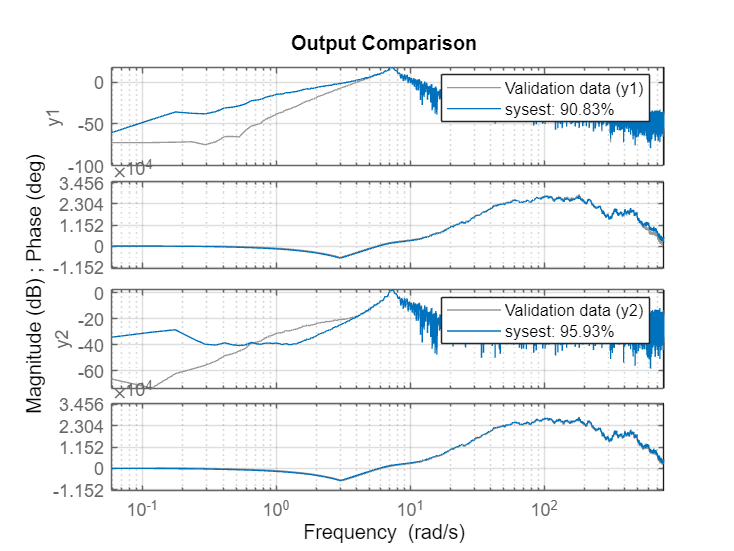

opt=compareOptions('initialcondition','zero');
figure(1); compare(DATA_freq,sysest,Inf,opt); grid on; legend()

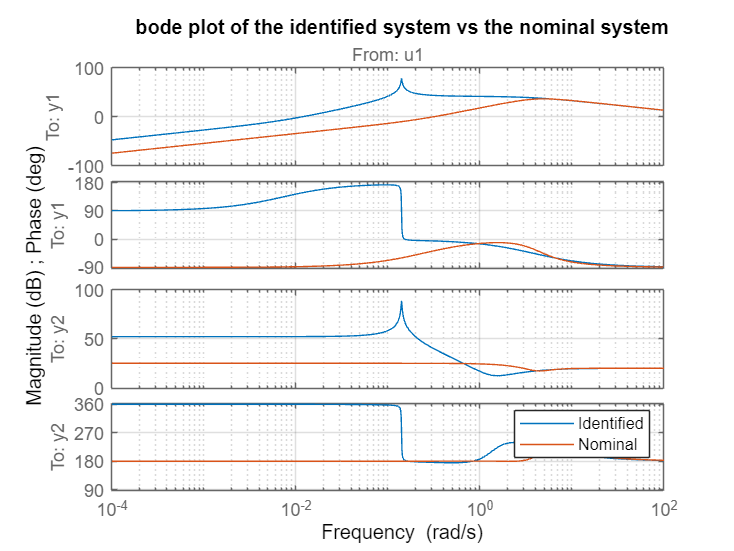

optimal=sum(Standard_Dev.^2);
figure(2); bode(sysest); grid on; hold on; bode(realmodel); title('bode plot of the identified system vs the nominal system'); legend('Identified','Nominal');

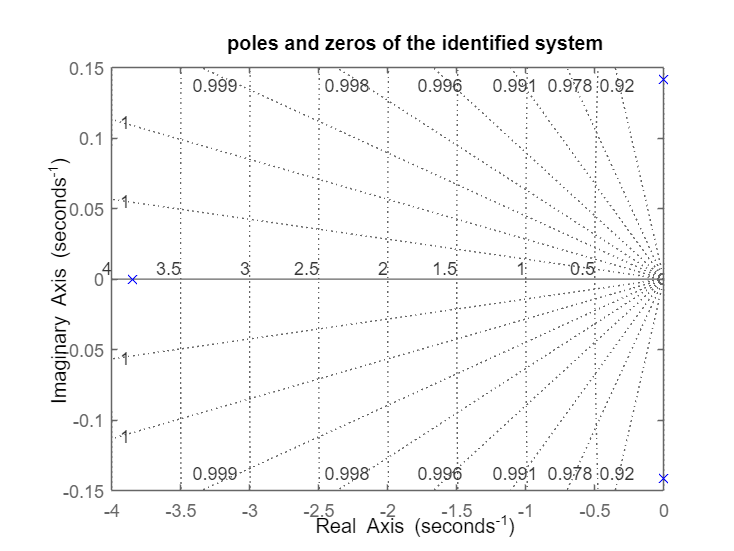

figure(3); pzplot(sysest, 'b*');grid on; title('poles and zeros of the identified system')

## **Optimization of the input sequence excitation:**

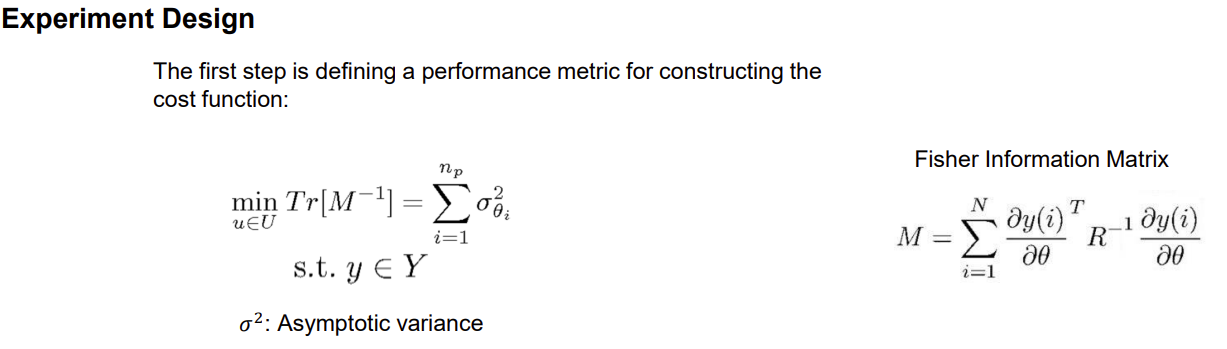

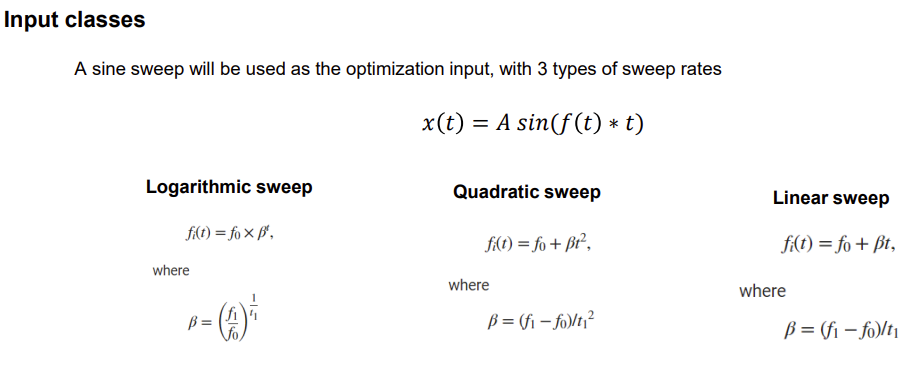

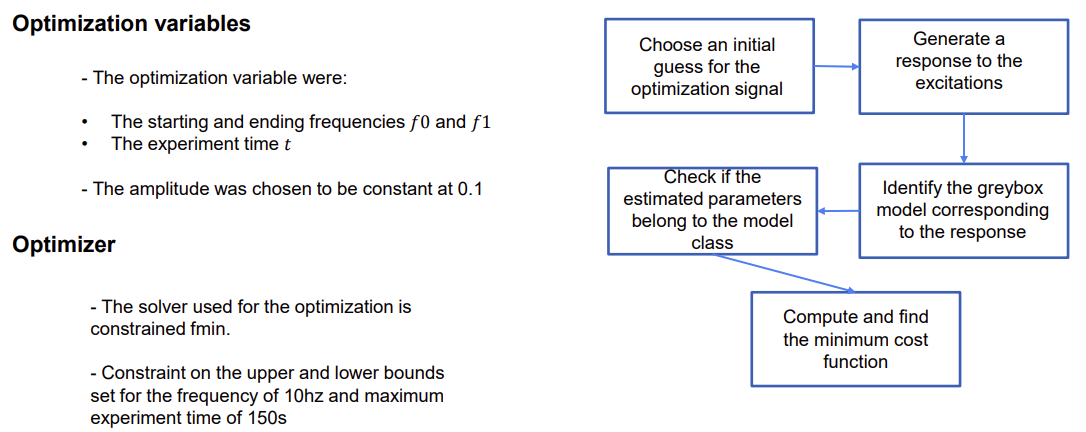

    0.0021

    0.9995    1.0000    1.0000    0.9989    0.9997    0.9995

    Params     Values     Standard_Dev    Relative_Dev
    ______    ________    ____________    ____________

      Xu      -0.10685     0.00013485          0.1262 
      Xq        0.1192      5.102e-06       0.0042803 
      Xd       -10.165      1.232e-05      0.00012121 
      Mu        -5.982       0.027686         0.46283 
      Mq       -2.6471      0.0072356         0.27334 
      Md        450.49       0.035738        0.007933 

    0.0020

    0.9996    1.0000    1.0000    0.9981    0.9996    0.9995

    Params     Values     Standard_Dev    Relative_Dev
    ______    ________    ____________    ____________

      Xu      -0.10685     

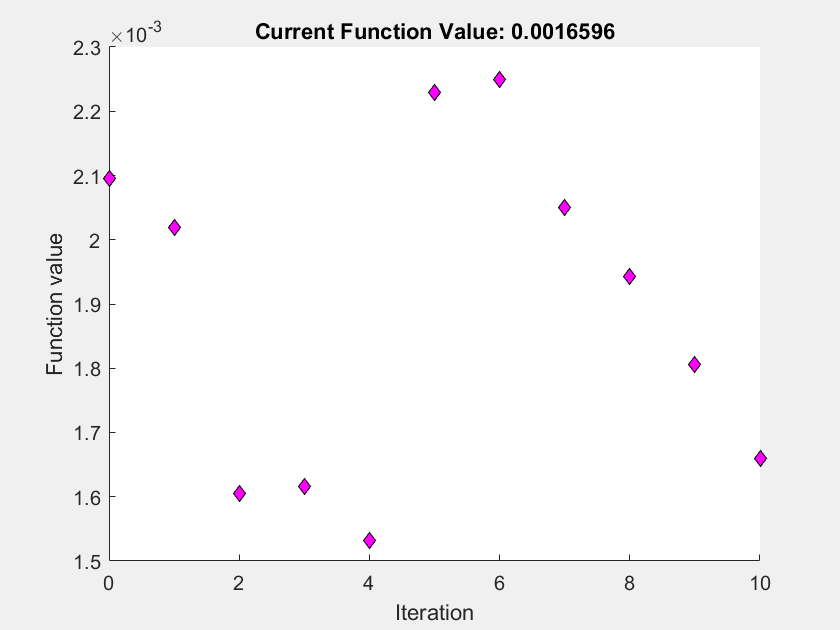


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Optimization of the signal classes (Requires dependencies)

Opt1f = @(u) Optimization1(u(1),u(2),u(3)); % Lin sine Sweep
J1f = @(u) sum(Opt1f(u).^2);
fun1f = @(u) J1f(u);
lb = [0,5,50]; ub = [1,10,150]; nonlcon=[];
A = []; b = []; Aeq = []; beq = [];
u10=[1 5 100];
tol = 1e-10;
options = optimoptions('fmincon','PlotFcns',@optimplotfval,'TolX',tol);
[u1f, fval1f] = fmincon(fun1f,u10,A,b,Aeq,beq,lb,ub,nonlcon,options);

    0.0016

    0.9999    1.0000    1.0000    0.9996    0.9997    0.9999

    Params     Values     Standard_Dev
    ______    ________    ____________

      Xu      -0.10681     0.00010605 
      Xq        0.1192     5.7064e-06 
      Xd       -10.165     1.4385e-05 
      Mu       -5.9728       0.025059 
      Mq       -2.6485      0.0062973 
      Md        450.68       0.031271 

    0.0018

    0.9999    1.0000    1.0000    0.9997    0.9999    0.9999

    Params     Values     Standard_Dev
    ______    ________    ____________

      Xu      -0.10681     0.00010908 
      Xq        0.1192     5.7092e-06 
      Xd       -10.165     1.4436e-05 
      Mu       -5.9774       0.026803 
      Mq       -2.6476       0.006448 
      Md        450.67       0.032079 

    0.0019

    0.99

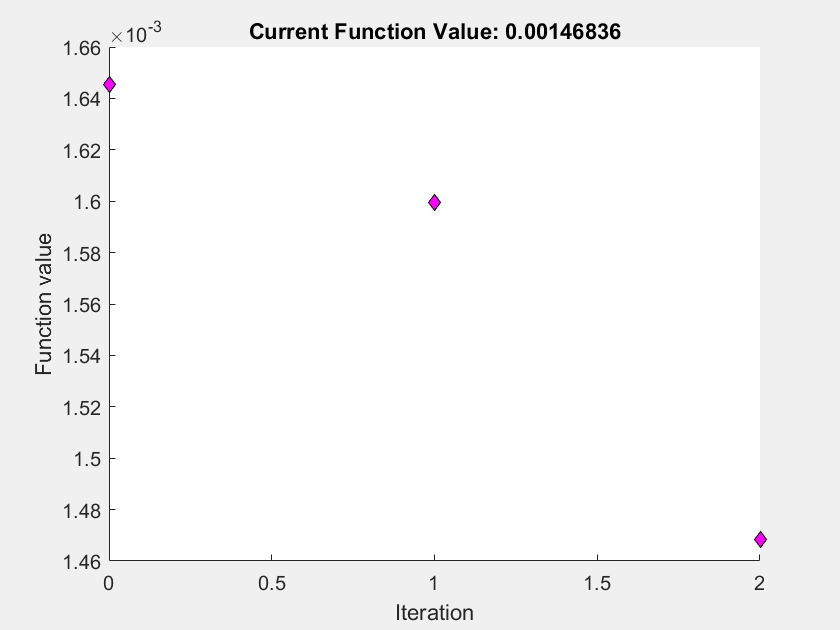


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Opt2f = @(u) Optimization2(u(1),u(2),u(3)); % Log sine Sweep
J2f = @(u) sum(Opt2f(u).^2);
fun2f = @(u) J2f(u);
lb = [0,5,50]; ub = [1,10,150]; nonlcon=[];
A = []; b = []; Aeq = []; beq = [];
u20=[1 5 100];
tol = 1e-10;
options = optimoptions('fmincon','PlotFcns',@optimplotfval,'TolX',tol);
[u2f, fval2f] = fmincon(fun2f,u10,A,b,Aeq,beq,lb,ub,nonlcon,options);

    0.0018

    0.9999    1.0000    1.0000    0.9986    0.9997    0.9999

    Params     Values     Standard_Dev
    ______    ________    ____________

      Xu      -0.10681     0.00010724 
      Xq        0.1192     5.7599e-06 
      Xd       -10.165     1.4476e-05 
      Mu       -5.9841       0.027403 
      Mq       -2.6471      0.0063442 
      Md        450.67       0.031367 

    0.0017

    0.9999    1.0000    1.0000    0.9994    1.0000    0.9999

    Params     Values     Standard_Dev
    ______    ________    ____________

      Xu      -0.10681     0.00010658 
      Xq        0.1192     5.7354e-06 
      Xd       -10.165      1.442e-05 
      Mu       -5.9789       0.025334 
      Mq       -2.6477      0.0063153 
      Md        450.67        0.03134 

    0.0015

    0.99

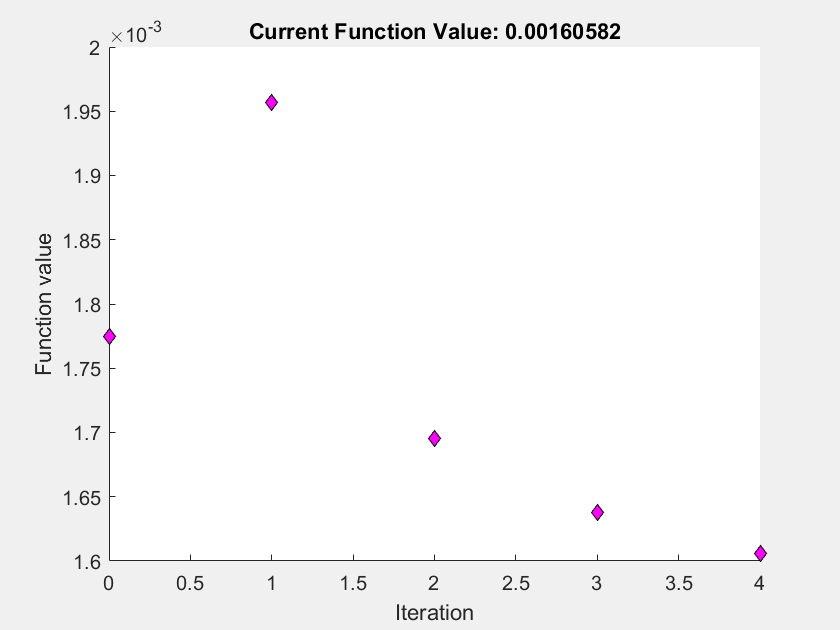


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Opt3f = @(u) Optimization3(u(1),u(2),u(3)); % quad sine Sweep
J3f = @(u) sum(Opt3f(u).^2);
fun3f = @(u) J3f(u);
lb = [0,5,50]; ub = [1,10,150]; nonlcon=[];
A = []; b = []; Aeq = []; beq = [];
u30=[1 5 100];
tol = 1e-10;
options = optimoptions('fmincon','PlotFcns',@optimplotfval,'TolX',tol);
[u3f, fval3f] = fmincon(fun3f,u10,A,b,Aeq,beq,lb,ub,nonlcon,options);

From the experiment, the most optimal signal sequence is the Logarithmic sine sweep with a minimum cost function 

of Tr = 1.4∗ 10−3.

The Signal is defined by the following parameters:

F0 = 0.549 (hz); F1= 5.98 (hz); Experiment time t = 99.99 (s)